% parameters
L=1;
T=0.1;
delta_x=0.1;
delta_t=.01;
Nx=L/delta_x

Nx = 10

Nt=T/delta_t

Nt = 10

u_t=1/(pi^2);

X=linspace(0,L,Nx+1)

X =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000


T=linspace(0,T,Nt+1)

T =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000



u=sin(pi*X);
U=zeros(Nx+1,Nt+1);
U(:,1)=u

U =          0         0         0         0         0         0         0         0         0         0         0
    0.3090         0         0         0         0         0         0         0         0         0         0
    0.5878         0         0         0         0         0         0         0         0         0         0
    0.8090         0         0         0         0         0         0         0         0         0         0
    0.9511         0         0         0         0         0         0         0         0         0         0
    1.0000         0         0         0         0         0         0         0         0         0         0
    0.9511         0         0         0         0         0         0         0         0         0         0
    0.8090         0         0         0         0         0         0         0         0         0         0
    0.5878         0         0         0         0         0         0         0         0         0        


sigma=u_t*delta_t/(2*delta_x^2)

sigma = 0.0507

A=diag((1+2*sigma)*ones(Nx-1,1)) + diag(-sigma*ones(Nx-2,1),-1)+ diag(-sigma*ones(Nx-2,1),1)

A =     1.1013   -0.0507         0         0         0         0         0         0         0
   -0.0507    1.1013   -0.0507         0         0         0         0         0         0
         0   -0.0507    1.1013   -0.0507         0         0         0         0         0
         0         0   -0.0507    1.1013   -0.0507         0         0         0         0
         0         0         0   -0.0507    1.1013   -0.0507         0         0         0
         0         0         0         0   -0.0507    1.1013   -0.0507         0         0
         0         0         0         0         0   -0.0507    1.1013   -0.0507         0
         0         0         0         0         0         0   -0.0507    1.1013   -0.0507
         0         0         0         0         0         0         0   -0.0507    1.1013


B=diag((1-2*sigma)*ones(Nx-1,1)) + diag(sigma*ones(Nx-2,1),-1)+ diag(sigma*ones(Nx-2,1),1)

B =     0.8987    0.0507         0         0         0         0         0         0         0
    0.0507    0.8987    0.0507         0         0         0         0         0         0
         0    0.0507    0.8987    0.0507         0         0         0         0         0
         0         0    0.0507    0.8987    0.0507         0         0         0         0
         0         0         0    0.0507    0.8987    0.0507         0         0         0
         0         0         0         0    0.0507    0.8987    0.0507         0         0
         0         0         0         0         0    0.0507    0.8987    0.0507         0
         0         0         0         0         0         0    0.0507    0.8987    0.0507
         0         0         0         0         0         0         0    0.0507    0.8987


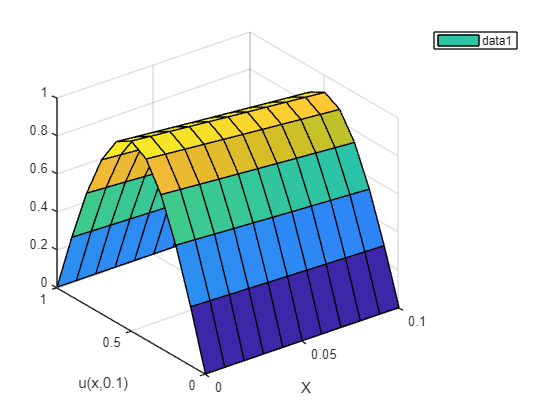


for n=2:Nt+1
    U(2:Nx,n)=A\(B*U(2:Nx, n-1));
end
surf(T,X,U)
xlabel('X');
ylabel('u(x,0.1)');
legend;
grid on;